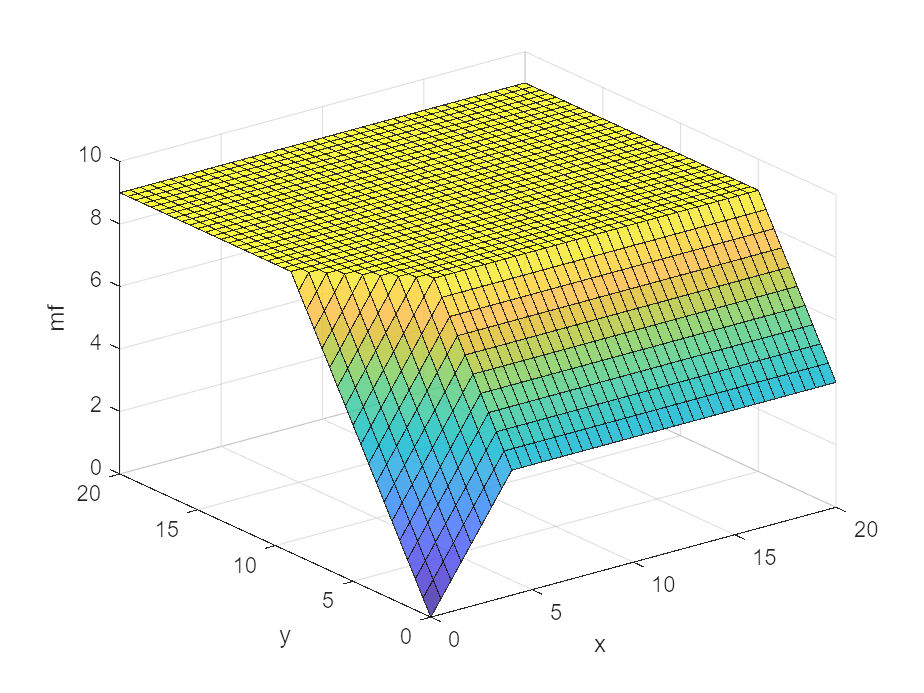

MF = zeros(length(0:0.5:20), length(0:0.5:20)); 
% create a matrix to put the maxflows of different x and y
X = 0:0.5:20;
Y = 0:0.5:20;
cnti = 1;
cntj = 1;

for i = 0:0.5:20
    cntj = 1;
    for j = 0:0.5:20
        x=i;
        y=j; %assign the values to x and y
        s = {'V1','V1','V2','V2','V2','V3','V3','V4','Vs','Vs'};
        t = {'V3','V4','V1','V3','V4','V4','Vt','Vt','V1','V2'};
        w = [2,2,4,1,4,6,9,7,y,x];
        G = digraph(s,t,w); %create the graph
        mf = maxflow(G,'Vs','Vt'); %calculate the maxflow from Vs to Vt
        MF(cnti, cntj) = mf; %put the maxflow into the matrix
        cntj = cntj + 1;
    end
    cnti = cnti + 1;
end

surf(X, Y, MF, EdgeAlpha = 0.8, FaceAlpha=0.8);
xlabel('x');ylabel('y');zlabel('mf');